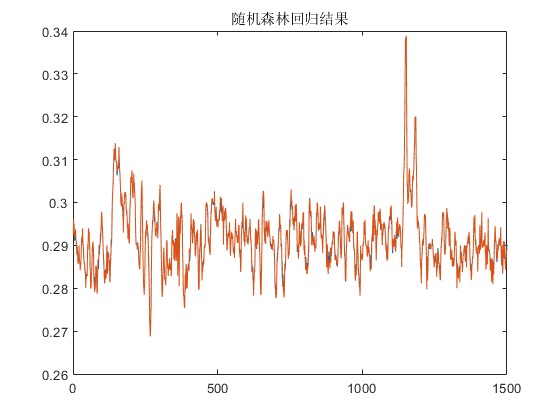

clearvars -except trainX trainY testX testY
%随机森林法，运行时间较长，请谨慎运行！
trainFeature=trainX;
trainLabel=trainY;
testFeature=testX;
B= TreeBagger(100,trainFeature,trainLabel,'Method','regression');  
for i=1:length(testFeature)
    result(1,i)=B.predict(testFeature(i,:));  
end
figure
plot(result);hold on;plot(testY);title('随机森林回归结果')

fprintf(num2str(mse(result-testY)))

9.7832e-05

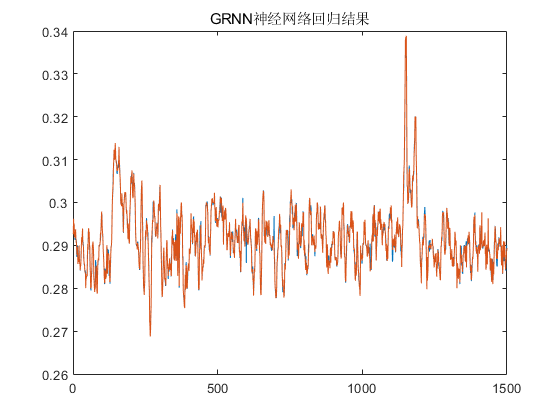

%GRNN神经网络回归
%归一化
[FeatureUniformed trainPS]=mapminmax(trainX',0,1);
[labelUniformed trainLabelPS]=mapminmax(trainY',0,1);
testFeatureUniformed=mapminmax('apply',testX',trainPS);
%%采用最佳方法建立GRNN网络
net=newgrnn(FeatureUniformed,labelUniformed,0.02);
%用训练集特征值归一化结果对测试集特征值进行归一化
result=sim(net,testFeatureUniformed);
%对结果进行反归一化
result=mapminmax('reverse',result,trainLabelPS)';
figure
plot(result);hold on;plot(testY);title('GRNN神经网络回归结果')

fprintf(num2str(mse(result-testY)))

9.0041e-07

%支持向量机 这个需要你安装SVM的包，因此就不演示了
% 归一化   
% [TSX TSXps]=mapminmax(trainX',0,1);
% [TS TSps]=mapminmax(trainY',0,1);
% testFeatureUniformed=mapminmax('apply',testX',TSXps);
% % 进行转置,以符合libsvm工具箱的数据格式要求
% TS = TS';TSX = TSX';
% 
% %% 选择回归预测分析最佳的SVM参数c&g
% % 首先进行粗略选择: 
% [bestmse,bestc,bestg] = SVMcgForRegress(TS,TSX,-10,10,-10,10,3,1,1,4);
% 
% % 打印粗略选择结果
% disp('打印粗略选择结果');
% str = sprintf( 'Best Cross Validation MSE = %g Best c = %g Best g = %g',bestmse,bestc,bestg);
% disp(str);
% 
% % 根据粗略选择的结果图再进行精细选择: 
% [bestmse,bestc,bestg] = SVMcgForRegress(TS,TSX,round(log2(bestc))-1,round(log2(bestc))+1,...
%     round(log2(bestg))-1,round(log2(bestg))+1,3,0.1,0.1,0.1);
% 
% % 打印精细选择结果
% disp('打印精细选择结果');
% str = sprintf( 'Best Cross Validation MSE = %g Best c = %g Best g = %g',bestmse,bestc,bestg);
% disp(str);
% 
% %% 利用回归预测分析最佳的参数进行SVM网络训练
% cmd = ['-c ', num2str(bestc), ' -g ', num2str(bestg) , ' -s 3 -p 0.01'];
% model = svmtrain(TS,TSX,cmd);
% 
% %% SVM网络回归预测
% [predict,mse,dec_data] = svmpredict(zeros(length(testFeature),1),testFeatureUniformed',model);
% predict = mapminmax('reverse',predict',TSps);
% result = predict';
% figure
% plot(result);hold on;plot(testY);title('支持向量机回归结果')
% fprintf(num2str(mse(result-testY)))